# Sistemas de segundo orden

## Sistema de segundo orden

La dínamica de un sistema de segundo orden, se puede representar medieante la siguiente transformada de Laplace


$$P\left(s\right)=k_{\mathrm{dc}\;} \frac{\omega {\;}_n^2 }{s^{2\;} +2\zeta \omega {\;}_n \;s+\omega_{n\;}^2 }$$


Donde

- $k_{\mathrm{dc}\;} >0\;\epsilon \;\Re \;$es la ganancia a una excitación constante, o corriente directa (DC), 

- $\omega {\;}_n >0\;\epsilon \;\Re \;$es la frecuencia natural oscilación del sistema.

- $\zeta$$>0\;\epsilon \;\Re$es el factor de amortiguamiento

El valor $k_{\textrm{dc}\;}$es aquel que se obtiene cuando el limite del sistema tienede al infinito.


$$\lim_{t\to \infty \;} \;P\left(s\right)=\lim_{s\to 0} \;P\left(s\right)=\lim_{s\to 0} \;\left(\frac{k_{\mathrm{dc}\;} \omega {\;}_n^2 }{s^{2\;} +2\zeta \omega {\;}_n \;s+\omega_{n\;}^2 }\right)=\frac{k_{\mathrm{dc}\;} \omega {\;}_n^2 }{{\left(0\right)}^{2\;} +2\zeta \omega {\;}_n \;\left(0\right)+\omega_{n\;}^2 }=\frac{k_{\mathrm{dc}\;} \omega {\;}_n^2 }{\omega_{n\;}^2 }{=\;k}_{\mathrm{dc}\;}$$


Para entender los efectos entre $\zeta$ y $\omega {\;}_n$en un sistema de segundo orden es necesario conocer el lugar geométrico de las raices del polinimio del denominador. Para ello se piensa en las raices "en general" de un polinomio de segundo orden.

clc;
close all;
clear all;
set(0, 'DefaultLineLineWidth', 2);

## Sistema subamortiguado, 0 < zeta < 1

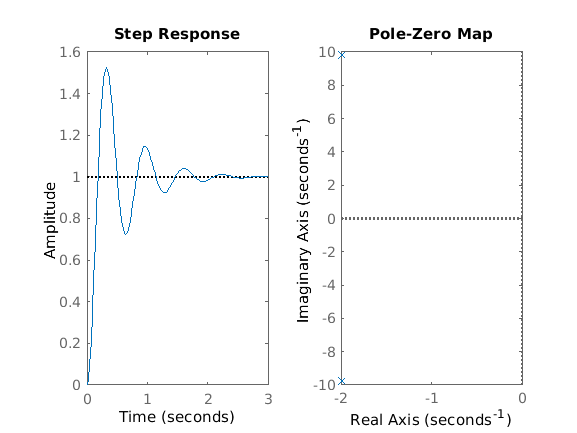

k_dc = 1;
w_n = 10;
zeta = 0.2;
s = tf('s');
G1 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);
figure(1);
subplot(1,2,2);
pzmap(G1);
subplot(1,2,1);
step(G1);

% axis([-3 1 -15 -10015]);

% 
% axis([0 3 0 2]);

## Sistema sobreamortiguado, zeta > 1

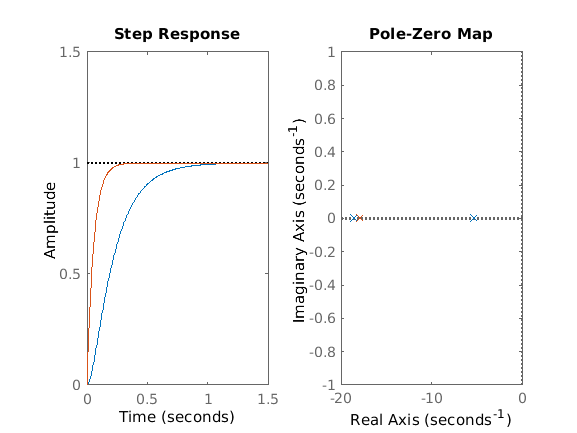

zeta = 1.2;
alpha = 18;

G2 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);
G1 = alpha/(s + alpha);


figure(2);
subplot(1,2,2);
pzmap(G2);
hold on;
pzmap(G1)
hold off;
% axis([-20 1 -1 1])

subplot(1,2,1)
step(G2)
hold on;
step(G1)
hold off;
axis([0 1.5 0 1.5]);

## Sistema criticamente amortiguado, zeta = 1


$$P\left(s\right)=k_{\mathrm{dc}\;} \frac{\omega {\;}_n^2 }{s^{2\;} +2\omega {\;}_n \;s+\omega_{n\;}^2 }=$$


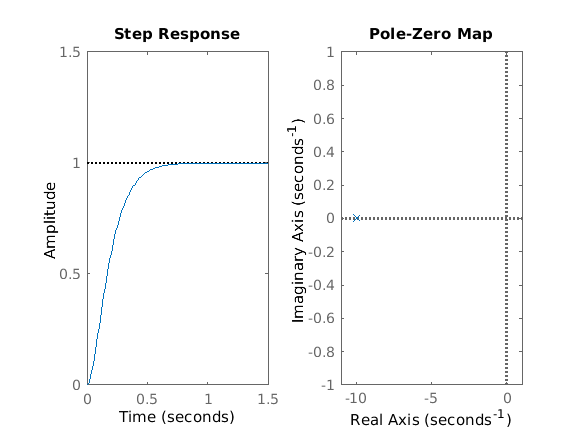

zeta = 1;

G3 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

figure(3);
subplot(1,2,2);
pzmap(G3)
axis([-11 1 -1 1])

subplot(1,2,1);
step(G3)
axis([0 1.5 0 1.5])

## Sistemas no amortiguados zeta = 0

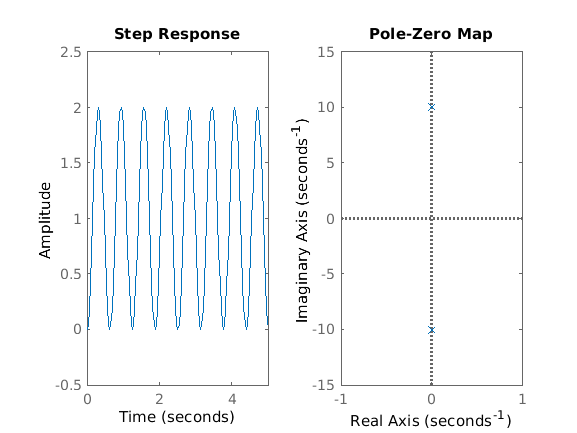

zeta = 0;

G4 = k_dc*w_n^2/(s^2 + 2*zeta*w_n*s + w_n^2);

figure(4);
subplot(1,2,2);
pzmap(G4)
axis([-1 1 -15 15])

subplot(1,2,1);
step(G4)
axis([0 5 -0.5 2.5])

## Diagrama de bode

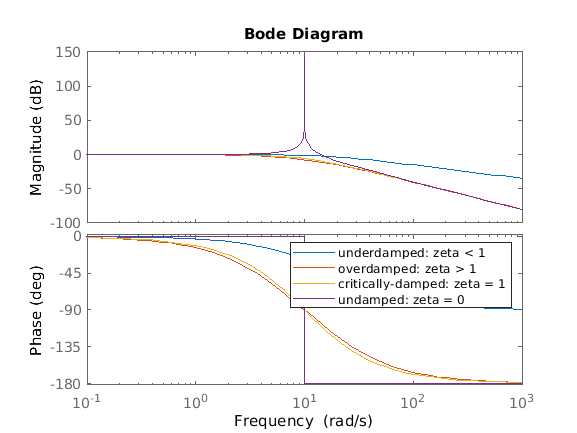

figure(5);
bode(G1,G2,G3,G4)
legend('underdamped: zeta < 1','overdamped: zeta > 1','critically-damped: zeta = 1','undamped: zeta = 0')